% Clear variables, figures
clear;
clf;
clc;
% Open Simulink model
open('humanSubject07_48dof_test.slx');

% Human arm parameters
% Shoulder
arm.shoulder.length = 0.47828; % [m]
arm.shoulder.radius = 0.02877; % [m]
arm.shoulder.mass = 2.4459; % [Kg]
arm.shoulder.moment_inertia = [0.0059341, 0.0010123, 0.0059341]; % [Kg*m^2]

% Forearm
arm.forearm.length = 0.2584; % [m]
arm.forearm.radius = 0.022803; % [m]
arm.forearm.mass = 1.578; % [Kg]
arm.forearm.moment_inertia = [0.0089856, 0.00041027, 0.0089856]; % [Kg*m^2]

% Hand
arm.hand.dimensions = [0.12916, 0.19374, 0.045607]; % [m]
arm.hand.mass = 0.4734; % [Kg]
arm.hand.moment_inertia = [0.0015629, 0.0007401900000000001, 0.0021389]; % [Kg*m^2]

% Markers
arm.markers.radius = 0.01; % [m]
marker.M_BaseRF = [arm.shoulder.radius+arm.markers.radius -3/4*arm.shoulder.length 0;
                   -arm.shoulder.radius-arm.markers.radius -3/4*arm.shoulder.length 0;
                   arm.shoulder.radius+arm.markers.radius -1/4*arm.shoulder.length 0;
                   -arm.shoulder.radius-arm.markers.radius -1/4*arm.shoulder.length 0;
                   arm.forearm.radius+arm.markers.radius -3/4*arm.forearm.length 0;
                   -arm.forearm.radius-arm.markers.radius -1/2*arm.forearm.length 0;
                   arm.forearm.radius+arm.markers.radius -1/4*arm.forearm.length 0;
                   0 -3/4*arm.hand.dimensions(2) arm.hand.dimensions(3)/2+arm.markers.radius;
                   0 -1/4*arm.hand.dimensions(2) arm.hand.dimensions(3)/2+arm.markers.radius];
marker.links = [1;
                1;
                1;
                1;
                2;
                2;

                2;
                3;
                3];
marker.m = height(marker.M_BaseRF); % Number of markers

% Align Reference frames
align.Rx = [1 0 0;
            0 0 -1;
            0 1 0];
align.Ry = [0 0 1;
            0 1 0;
            -1 0 0];
align.Rz = [0 -1 0;
            1 0 0;
            0 0 1];

% Simulation
output = sim("humanSubject07_48dof_test.slx");

#### FORWARD KINEMATICS


$$\pmatrix{p_{M_1}^W \cr p_{M_2}^W \cr p_{M_3}^W \cr p_{M_4}^W \cr p_{M_5}^W \cr p_{M_6}^W \cr p_{M_7}^W} = \pmatrix{T_{M_1}^{W}(q1,q2,q3) \cr T_{M_2}^{W}(q1,q2,q3) \cr T_{M_3}^{W}(q1,q2,q3) \cr T_{M_4}^{W}(q1,q2,q3) \cr T_{M_5}^{W}(q1,q2,q3,q4) \cr T_{M_6}^{W}(q1,q2,q3,q4) \cr T_{M_7}^{W}(q1,q2,q3,q4)} \cdot \pmatrix{p_{M_1}^{M_1} \cr p_{M_2}^^{M_2} \cr p_{M_3}^^{M_3} \cr p_{M_4}^^{M_4} \cr p_{M_5}^^{M_5} \cr p_{M_6}^^{M_6} \cr p_{M_7}^^{M_7}} \qquad \Longrightarrow \qquad p = \Phi(q)$$


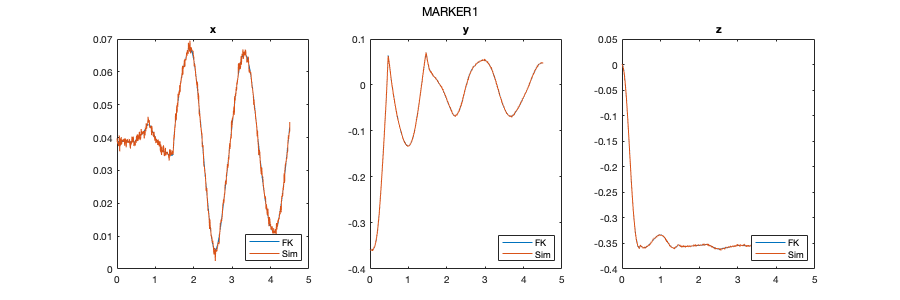

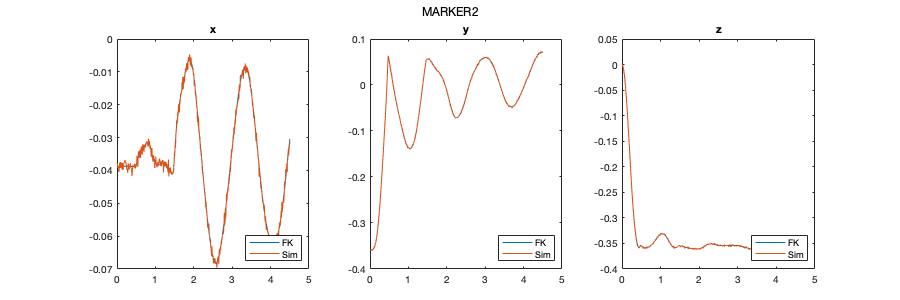

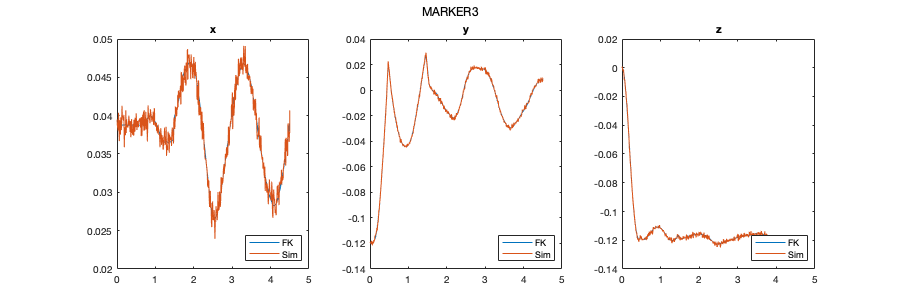

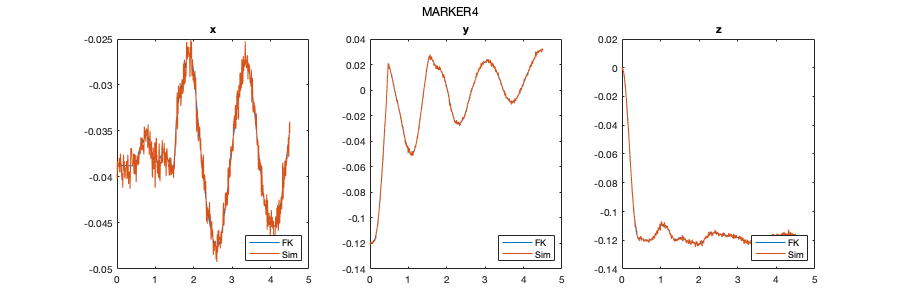

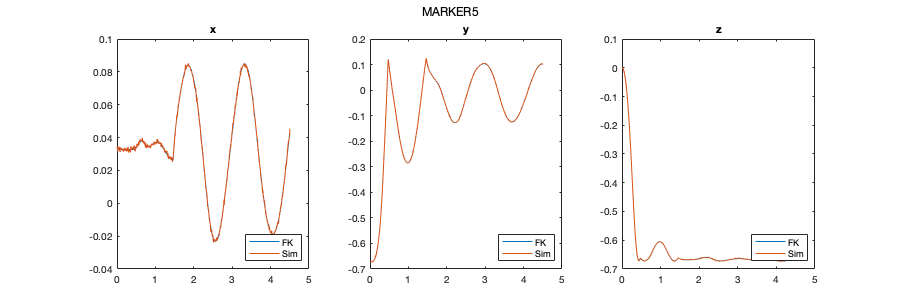

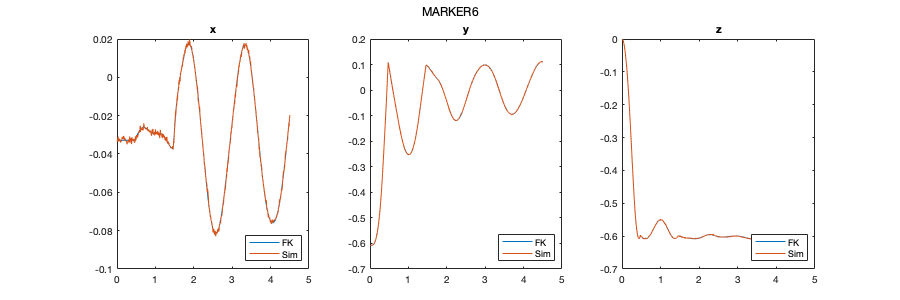

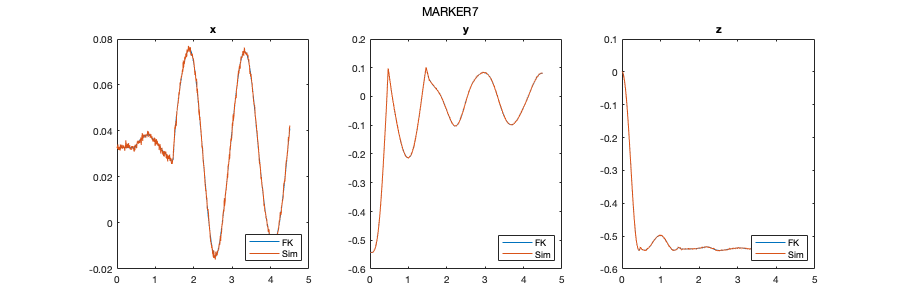

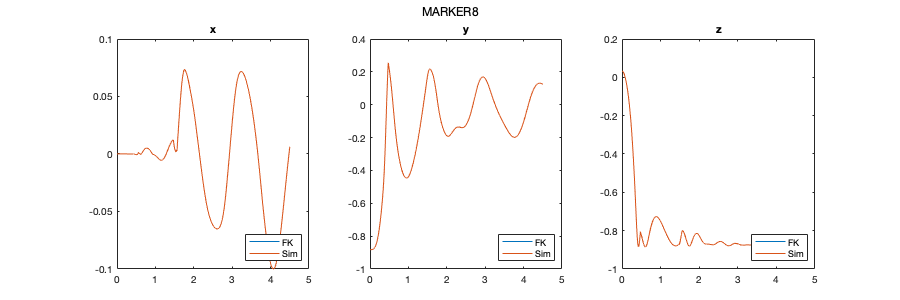

% %
% %% SHOULDER
% %
% syms q1 q2 q3 q4 q5 q6 q7 a1 a2 a3 sh_len for_len ;
% shoulder.Rx = [cos(q1) -sin(q1) 0;
%                sin(q1) cos(q1) 0;
%                0 0 1];
% shoulder.Ry = [cos(q2) -sin(q2) 0;
%                sin(q2) cos(q2) 0;
%                0 0 1];
% shoulder.Rz = [cos(q3) -sin(q3) 0;
%                sin(q3) cos(q3) 0;
%                0 0 1];
% 
% % ROTATION: W --> B_shoulder
% shoulder.RW_x = align.Rz * align.Rx * shoulder.Rx; % W --> shoulder.Rx
% shoulder.Rx_y = align.Ry * align.Rz * shoulder.Ry; % shoulder.Rx --> shoulder.Ry
% shoulder.Ry_BS = align.Rx * align.Ry * shoulder.Rz; % shoulder.Ry --> B_shoulder
% shoulder.RW_BS = shoulder.RW_x * shoulder.Rx_y * shoulder.Ry_BS; % W --> B_shoulder
% 
% % TRANSLATION: Marker wrt B_shoulder
% marker.trans_BS_M = [a1; a2; a3];
% % ROTATION+TRANSLATION: Marker to World
% marker.TW_Mshou = [shoulder.RW_BS shoulder.RW_BS * marker.trans_BS_M;0 0 0 1];
% 
% %
% %% ELBOW
% %
% elbow.Rx = [cos(q4) -sin(q4) 0;
%             sin(q4) cos(q4) 0;
%             0 0 1];
% 
% % TRANSLATION: F_shoulder wrt B_shoulder
% shoulder.trans_BS_FS = [0; -sh_len; 0];
% % ROTATION+TRANSLATION: F_shoulder to World
% shoulder.TW_FS = [shoulder.RW_BS shoulder.RW_BS * shoulder.trans_BS_FS;0 0 0 1];
% % ROTATION: F_shoulder --> B_elbow
% elbow.RFS_x = align.Rz * align.Rx * elbow.Rx; % F_shoulder --> elbow.Rx
% elbow.Rx_z = (align.Rz * align.Rx)'; % elbow.Rx --> elbow.Rz
% elbow.RFS_BE = elbow.RFS_x * elbow.Rx_z; % F_shoulder --> B_elbow
% 
% % TRANSLATION: Marker wrt B_elbow
% marker.trans_BE_M = [a1; a2; a3];
% % ROTATION+TRANSLATION: Marker5 to F_shoulder
% marker.TFS_M = [elbow.RFS_BE elbow.RFS_BE * marker.trans_BE_M;0 0 0 1];
% % ROTATION+TRANSLATION: Marker5 to World
% marker.TW_Mfore = shoulder.TW_FS * marker.TFS_M;
% 
% %
% %% WRIST
% %
% wrist.Rx = [cos(q5) -sin(q5) 0;
%             sin(q5) cos(q5) 0;
%             0 0 1];
% wrist.Ry = [cos(q6) -sin(q6) 0;
%             sin(q6) cos(q6) 0;
%             0 0 1];
% wrist.Rz = [cos(q7) -sin(q7) 0;
%             sin(q7) cos(q7) 0;
%             0 0 1];
% 
% % TRANSLATION: F_elbow wrt B_elbow
% elbow.trans_BE_FE = [0; -for_len; 0];
% % ROTATION+TRANSLATION: F_elbow to F_shoulder
% elbow.TFS_FE = [elbow.RFS_BE elbow.RFS_BE * elbow.trans_BE_FE;0 0 0 1];
% % ROTATION+TRANSLATION: F_elbow to W
% elbow.TW_FE = shoulder.TW_FS * elbow.TFS_FE;
% % ROTATION: F_elbow --> B_wrist
% wrist.RFE_x = align.Rz * align.Rx * wrist.Rx; % F_elbow --> wrist.Rx
% wrist.Rx_y = align.Ry * align.Rz * wrist.Ry; % wrist.Rx --> wrist.Ry
% wrist.Ry_BW = align.Rx * align.Ry * wrist.Rz; % wrist.Ry --> B_wrist
% wrist.RFE_BW = wrist.RFE_x * wrist.Rx_y * wrist.Ry_BW; % F_elbow --> B_wrist
% 
% % TRANSLATION: Marker wrt B_wrist
% marker.trans_BW_M = [a1; a2; a3];
% % ROTATION+TRANSLATION: Marker8 to F_elbow
% marker.TFE_M = [wrist.RFE_BW wrist.RFE_BW * marker.trans_BW_M;0 0 0 1];
% % ROTATION+TRANSLATION: Marker8 to World
% marker.TW_Mhand = elbow.TW_FE * marker.TFE_M;

% Plot markers position (FK vs Simulation(with a bit of noise))
gcf = cell(marker.m*2, 1);
title_name = cell(marker.m*2, 1);
for i = 1 : marker.m

    gcf{i} = figure(i);
    title_name{i} = strcat('MARKER ', num2str(i));
    sgtitle(title_name{i}) 
    set(gcf{i}, 'position', [10, 10, 900, 300]);
    subplot(1,3,1);
    plot(output.markers_pos_FK.time, squeeze(output.markers_pos_FK.signals.values(i,1,:)));
    hold on;
    plot(output.markers_pos_FK.time, squeeze(output.markers_pos_sim.signals.values(:,3*(i-1)+1)));
    legend('FK', 'Sim', 'Location', 'southeast');
    title('x');
    hold off;
    subplot(1,3,2);
    plot(output.markers_pos_FK.time, squeeze(output.markers_pos_FK.signals.values(i,2,:)));
    hold on;
    plot(output.markers_pos_FK.time, squeeze(output.markers_pos_sim.signals.values(:,3*(i-1)+2)));
    legend('FK', 'Sim', 'Location', 'southeast');
    title('y');
    hold off;
    subplot(1,3,3);
    plot(output.markers_pos_FK.time, squeeze(output.markers_pos_FK.signals.values(i,3,:)));
    hold on;
    plot(output.markers_pos_FK.time, squeeze(output.markers_pos_sim.signals.values(:,3*(i-1)+3)));
    legend('FK', 'Sim', 'Location', 'southeast');
    title('z');
    hold off;
end

#### JACOBIAN COMPUTATION


$$\pmatrix{\dot{p}_{M_1} \cr \dot{p}_{M_2} \cr .. \cr \dot{p}_{M_M}} = \pmatrix{J_1 \cr J_2 \cr ..  \cr J_M } \cdot q \qquad \Longrightarrow \qquad  \dot{p} = J(q) \cdot  \dot{q} $$


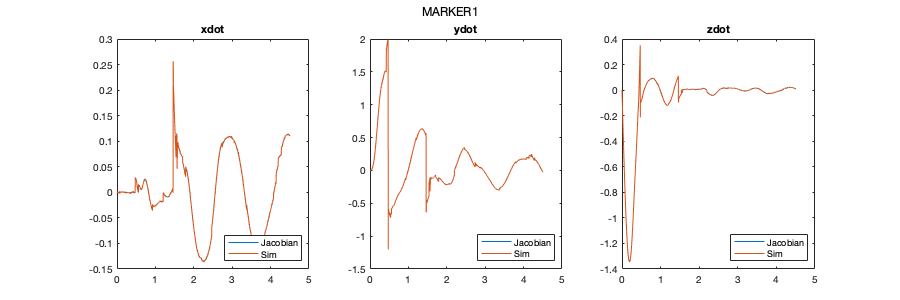

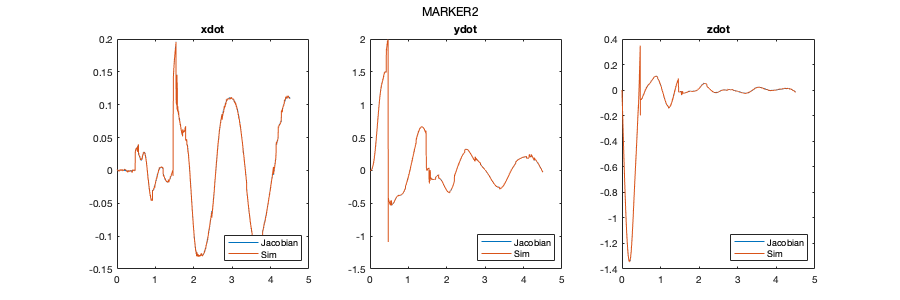

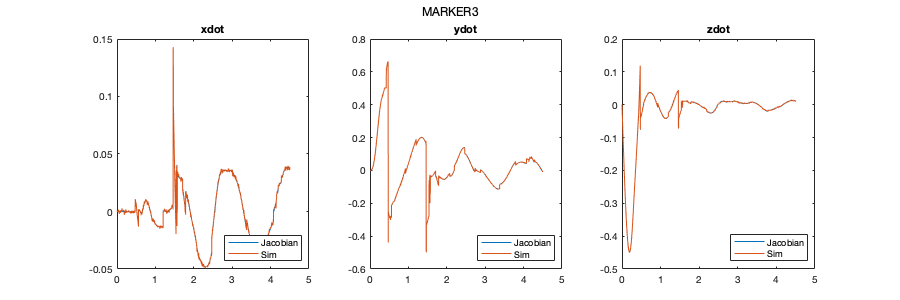

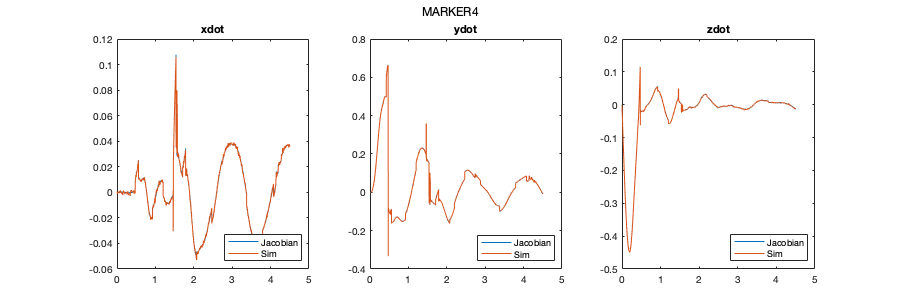

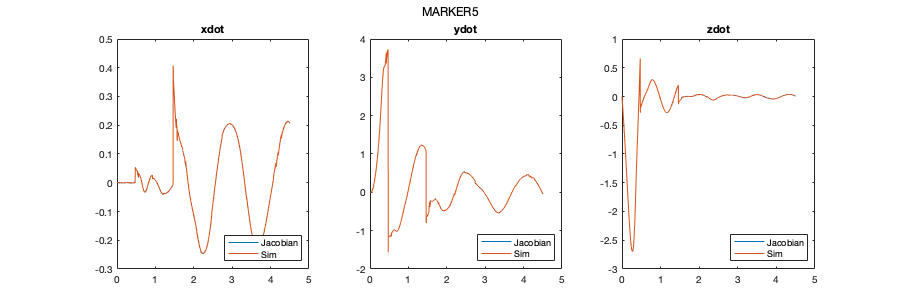

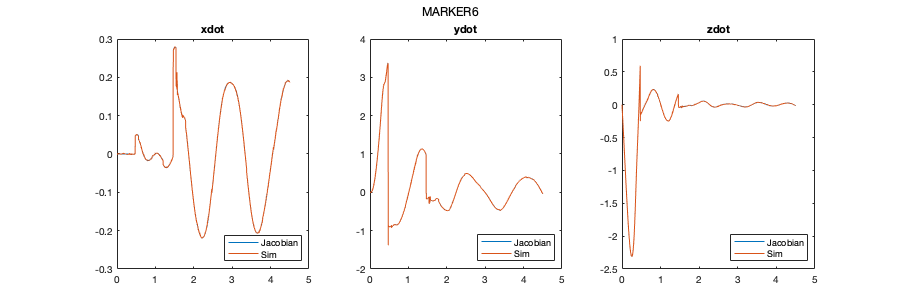

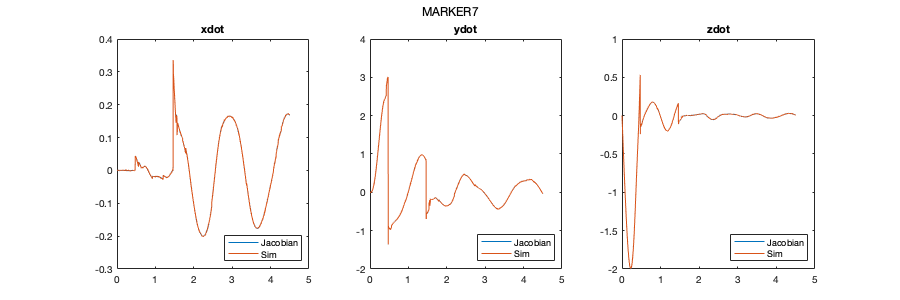

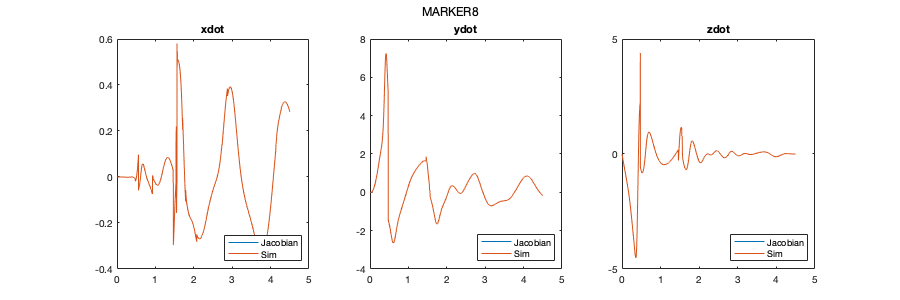

% % PHI COMPUTATION
% marker.Phi_shou =  marker.TW_Mshou(1:3,4);
% marker.Phi_fore =  marker.TW_Mfore(1:3,4);
% marker.Phi_hand =  marker.TW_Mhand(1:3,4);
% 
% q = [q1, q2, q3, q4, q5, q6, q7];
% jacobian_shou = zeros(3, 7);
% jacobian_fore = zeros(3, 7);
% jacobian_hand = zeros(3, 7);
% 
% % Shoulder
% jacobian_shou = diff(marker.Phi_shou, q(1));
% jacobian_shou(:,2) = diff(marker.Phi_shou, q(2));
% jacobian_shou(:,3) = diff(marker.Phi_shou, q(3));
% jacobian_shou(:,4) = diff(marker.Phi_shou, q(4));
% jacobian_shou(:,5) = diff(marker.Phi_shou, q(5));
% jacobian_shou(:,6) = diff(marker.Phi_shou, q(6));
% jacobian_shou(:,7) = diff(marker.Phi_shou, q(7));
% 
% % Forearm
% jacobian_fore = diff(marker.Phi_fore, q(1));
% jacobian_fore(:,2) = diff(marker.Phi_fore, q(2));
% jacobian_fore(:,3) = diff(marker.Phi_fore, q(3));
% jacobian_fore(:,4) = diff(marker.Phi_fore, q(4));
% jacobian_fore(:,5) = diff(marker.Phi_fore, q(5));
% jacobian_fore(:,6) = diff(marker.Phi_fore, q(6));
% jacobian_fore(:,7) = diff(marker.Phi_fore, q(7));
% 
% % Hand
% jacobian_hand = diff(marker.Phi_hand, q(1));
% jacobian_hand(:,2) = diff(marker.Phi_hand, q(2));
% jacobian_hand(:,3) = diff(marker.Phi_hand, q(3));
% jacobian_hand(:,4) = diff(marker.Phi_hand, q(4));
% jacobian_hand(:,5) = diff(marker.Phi_hand, q(5));
% jacobian_hand(:,6) = diff(marker.Phi_hand, q(6));
% jacobian_hand(:,7) = diff(marker.Phi_hand, q(7));

% Plot markers velocities (Jacobian vs Simulation(with a bit of noise))
j = marker.m+1;
for i = 1 : marker.m

    gcf{j} = figure(j);
    title_name{i} = strcat('MARKER ', num2str(i));
    sgtitle(title_name{i}) 
    set(gcf{j}, 'position', [10, 10, 900, 300]);
    subplot(1,3,1);
    plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_JAC.signals.values(:, 3*(i-1)+1)));
    hold on;
    plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_sim.signals.values(:, 3*(i-1)+1)));
    legend('Jacobian', 'Sim', 'Location', 'southeast');
    title('xdot');
    hold off;
    subplot(1,3,2);
    plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_JAC.signals.values(:, 3*(i-1)+2)));
    hold on;
    plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_sim.signals.values(:, 3*(i-1)+2)));
    legend('Jacobian', 'Sim', 'Location', 'southeast');
    title('ydot');
    hold off;
    subplot(1,3,3);
    plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_JAC.signals.values(:, 3*(i-1)+3)));
    hold on;
    plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_sim.signals.values(:, 3*(i-1)+3)));
    legend('Jacobian', 'Sim', 'Location', 'southeast');
    title('zdot');
    hold off;
    j = j + 1;
end

#### LS APPROACH


$$\dot{q} = J^{\dagger}(q) \cdot  \dot{p}  \qquad \longrightarrow \qquad $$


% LS APPROACH (PseudoInverse)
% j = 2 * marker.m + 1;
% for i = 1 : 7
% 
%     gcf{j} = figure(j);
%     title_name{i} = strcat('q', num2str(i)); 
%     set(gcf{j}, 'position', [10, 10, 900, 300]);
%     plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_JAC.signals.values(:, 3*(i-1)+1)));
%     hold on;
%     plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_sim.signals.values(:, 3*(i-1)+1)));
%     legend('Jacobian', 'Sim', 'Location', 'southeast');
%     title('q1 vs q1_LS');
%     hold off;
%     subplot(1,3,2);
%     plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_JAC.signals.values(:, 3*(i-1)+2)));
%     hold on;
%     plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_sim.signals.values(:, 3*(i-1)+2)));
%     legend('Jacobian', 'Sim', 'Location', 'southeast');
%     title('ydot');
%     hold off;
%     subplot(1,3,3);
%     plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_JAC.signals.values(:, 3*(i-1)+3)));
%     hold on;
%     plot(output.markers_vel_JAC.time, squeeze(output.markers_vel_sim.signals.values(:, 3*(i-1)+3)));
%     legend('Jacobian', 'Sim', 'Location', 'southeast');
%     title('zdot');
%     hold off;
%     j = j + 1;
% end